## **Driver test program to check Clothoids library**

**Test G2 clothoid**

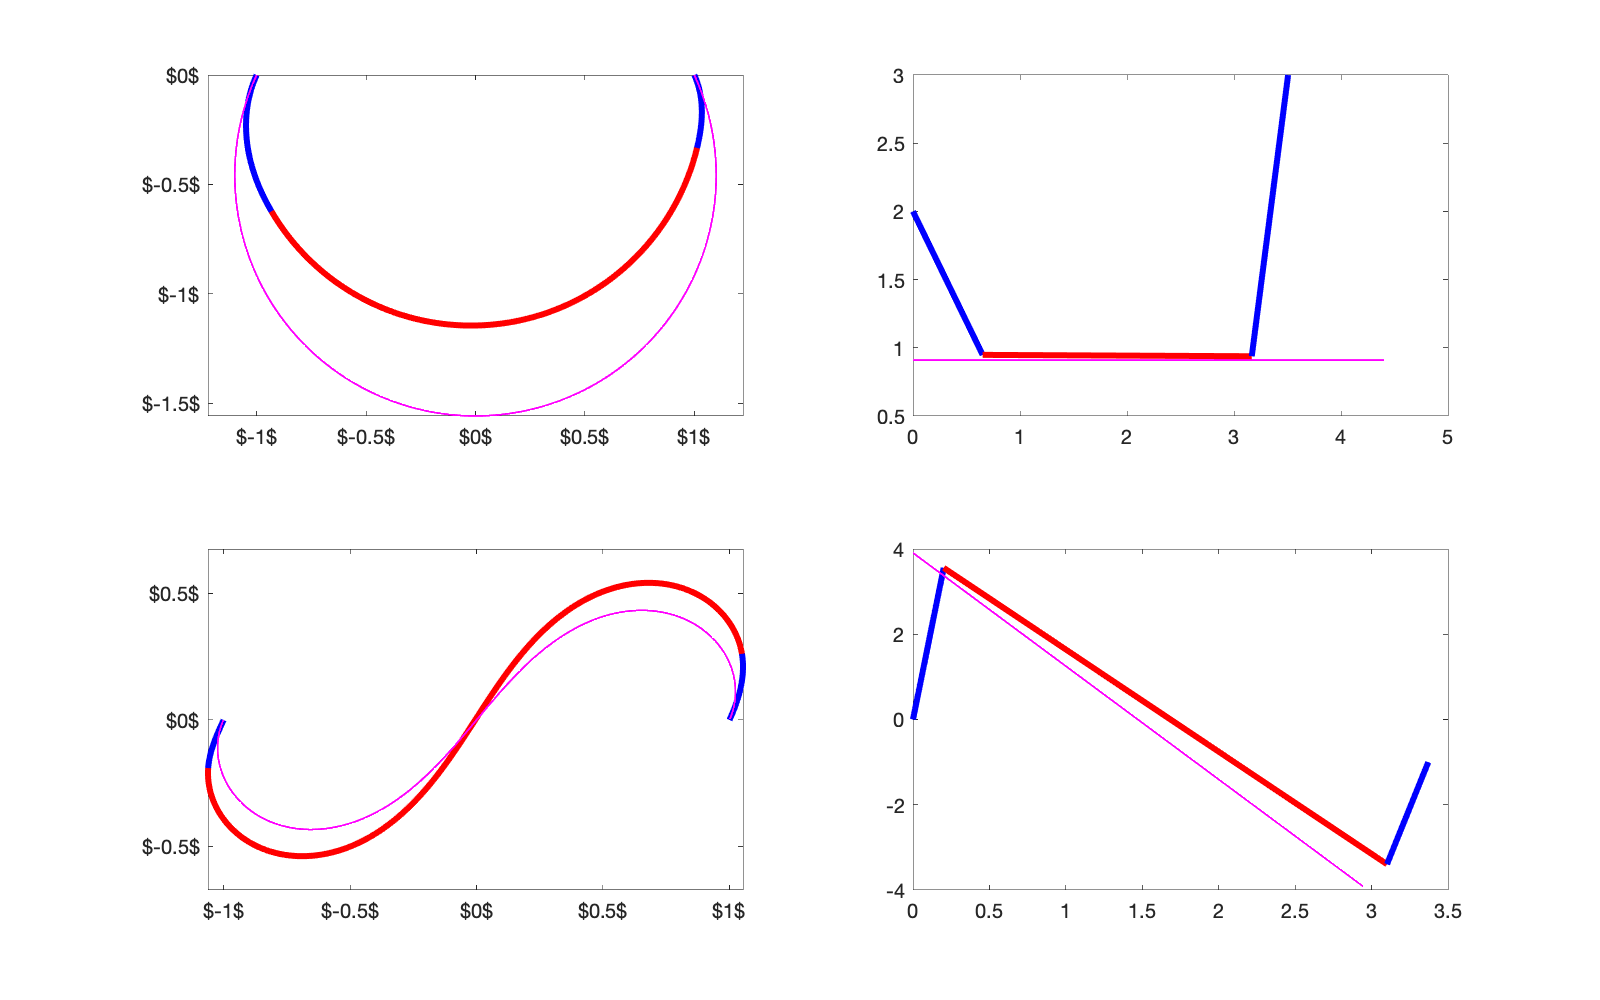

close all;

x0     = -1;
y0     = 0;
theta0 = [-2,-2];
kappa0 = [2,0];

x1     = 1;
y1     = 0;
theta1 = [2,-2];
kappa1 = [3,-1];

close all;
figure('Position',[1,1,800,500]);

S = ClothoidList();
C = ClothoidCurve();

k = 0;
for ii=1:2
  k = k+1;
  subplot(2,2,k);
  %subaxis(2,2,k, 'Spacing', 0.03, 'Padding', 0.02, 'Margin', 0.02);
  iter = S.build_3arcG2(x0,y0,theta0(ii),kappa0(ii),x1,y1,theta1(ii),kappa1(ii));
  S.plot();
  axis equal;
  
  iter = C.build_G1(x0,y0,theta0(ii),x1,y1,theta1(ii));
  C.plot(1000,'-m','Linewidth',1);

  set(gca,'DataAspectRatio',[1,1,1]);
  set(gca,'XTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
  set(gca,'XTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});
  set(gca,'YTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
  set(gca,'YTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});
  
  k = k+1;
  subplot(2,2,k);
  %subaxis(2,2,k, 'Spacing', 0.03, 'Padding', 0.02, 'Margin', 0.02);
  S.plotCurvature(1000);
  C.plotCurvature(1000,'-m','Linewidth',1);
  
  %X = [ 0, 1];
  %K = [ SG.k0, SG.k0+SG.L*SG.dk ];
  %plot( X, K, '-m', 'LineWidth', 1 );
  
  if false
    set(gca,'XTick',[0,0.25,0.5,0.75,1]);
    set(gca,'XTickLabel',{'$0$','$0.25$','$0.5$','$0.75$','$1$'});
    if k == 2
    set(gca,'YTick',[0.5,1,1.5,2,2.5,3]);
    set(gca,'YTickLabel',{'$0.5$','$1$','$1.5$','$2$','$2.5$','$3$'});
    else
    set(gca,'YTick',[-3,-1.5,0,1.5,3]);
    set(gca,'YTickLabel',{'$-3$','$-1.5$','$0$','$1.5$','$3$'});
    end
  end
end